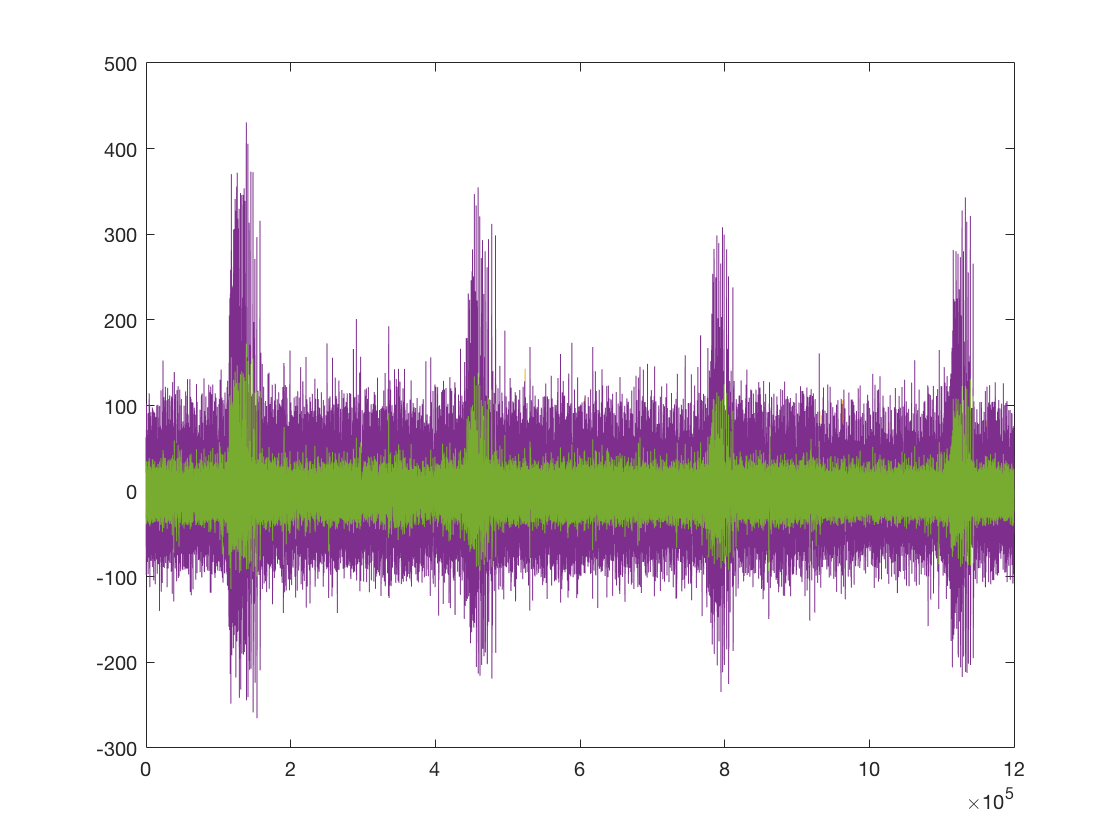

% MODE: BIPOLAR, EEG
% pos: e22
% neg: e64
% 
% WAVEFORM: 
% SHAPE: SQUARE BIPHASIC pos/neg
% DURATION/PHASE: 100 us ?
% AMPLITUDE/PHASE: 200 uA
% 
% ----------------------------
%
% 
% e22: labled ictal events only; interic1   tal events are hidden in the baseline noise.
% 
% e64: labeled ictal events only; possibly, interictal events are hidden in the baseline noise.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Author: LilyHeAsamiko
% 
data1 = load('EEG_slice01_01.mat');
data2 = load('EEG_slice01_02.mat');
data3 = load('EEG_slice01_03.mat');
data4 = load('EEG_slice01_04.mat');

fs = data1.fs;
EEG1 = data1.data;
EEG2 = data2.data;
EEG3 = data3.data;
EEG4 = data4.data;

N = length(EEG1);%sample number
T = N/fs; %600s
bin = N/T; %samples per bin(1s)
N_bin = N/bin; % bin number
ch = 1;%1 2 3 4

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % tonic seizure
% % 3min , 1min pre-seizure, 1min seizure, 1min post-seizure

EEG_avg = mean([EEG1, EEG2, EEG3, EEG4], 2);
figure
%% onset detection
% average of the multi-channels

plot(EEG1)
hold on
plot(EEG2)
hold on
plot(EEG3)
hold on
plot(EEG4)
hold on
plot(EEG_avg)


EEG_t = [EEG1, EEG2, EEG3, EEG4, EEG_avg];
for win = 1: N_bin    
    EEG_t_avg(win, :) = mean(EEG_t((win-1)*bin+1:(win-1)*bin+bin,:),1);
end

% %%%%%%%

% onset based on decorrelation time: the first t ensures, local minimum of
% autocorrelation: abs(corr< 1/e),  here let e be 2
[rho,pval] = corr(EEG_t_avg');
tau = autocorr(EEG_t_avg(:)', 'NumLags', 600)

tau =     1.0000   -0.5198    0.0360   -0.0362    0.0020    0.0495   -0.0143    0.0138   -0.0221    0.0361   -0.0247    0.0169    0.0097   -0.0625    0.1109   -0.0859    0.0288    0.0050    0.0121    0.0007    0.0266   -0.0695    0.0481    0.0052   -0.0106    0.0160   -0.0140    0.0071    0.0017    0.0259   -0.0236    0.0262   -0.0291    0.0431   -0.0288   -0.0330    0.1084   -0.0803    0.0218   -0.0127   -0.0019    0.0321    0.0181   -0.0348    0.0386   -0.0617    0.0457    0.0059   -0.0105    0.0243


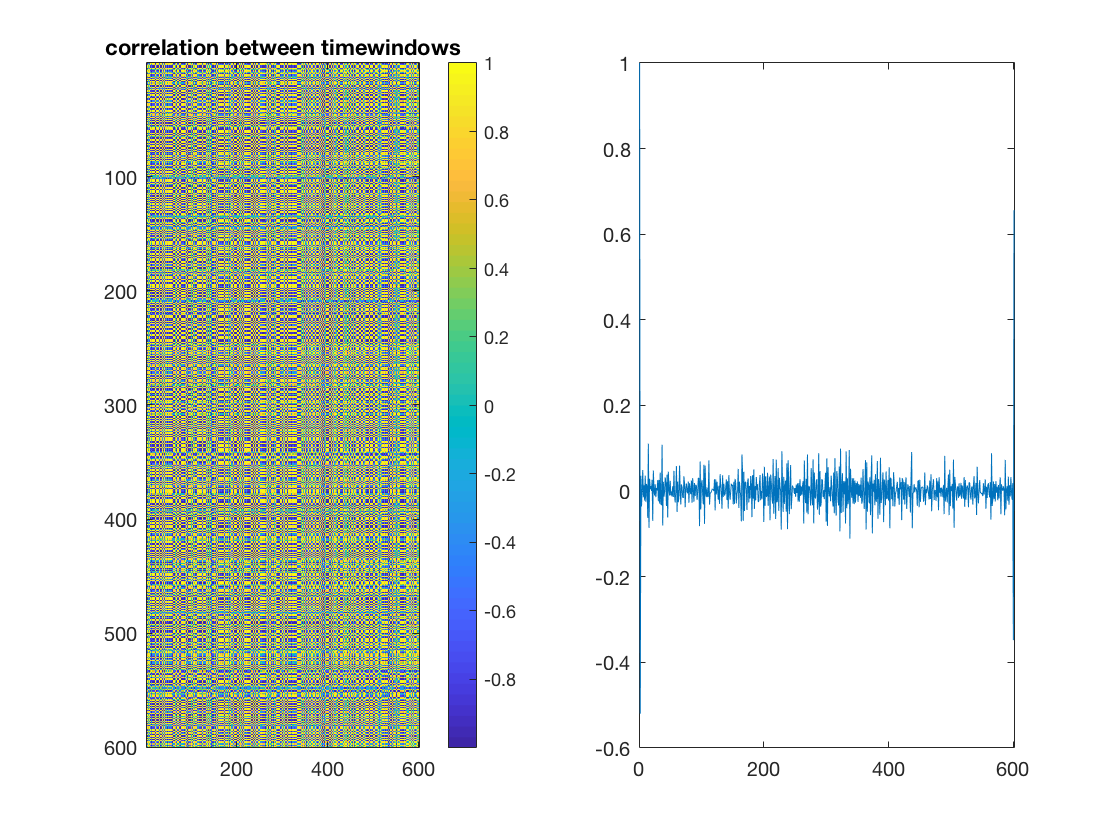

figure,
subplot(1,2,1)  
%pcolor(rho);
imagesc(rho)
title('correlation between timewindows');
colorbar
subplot(1,2,2)
plot(tau);

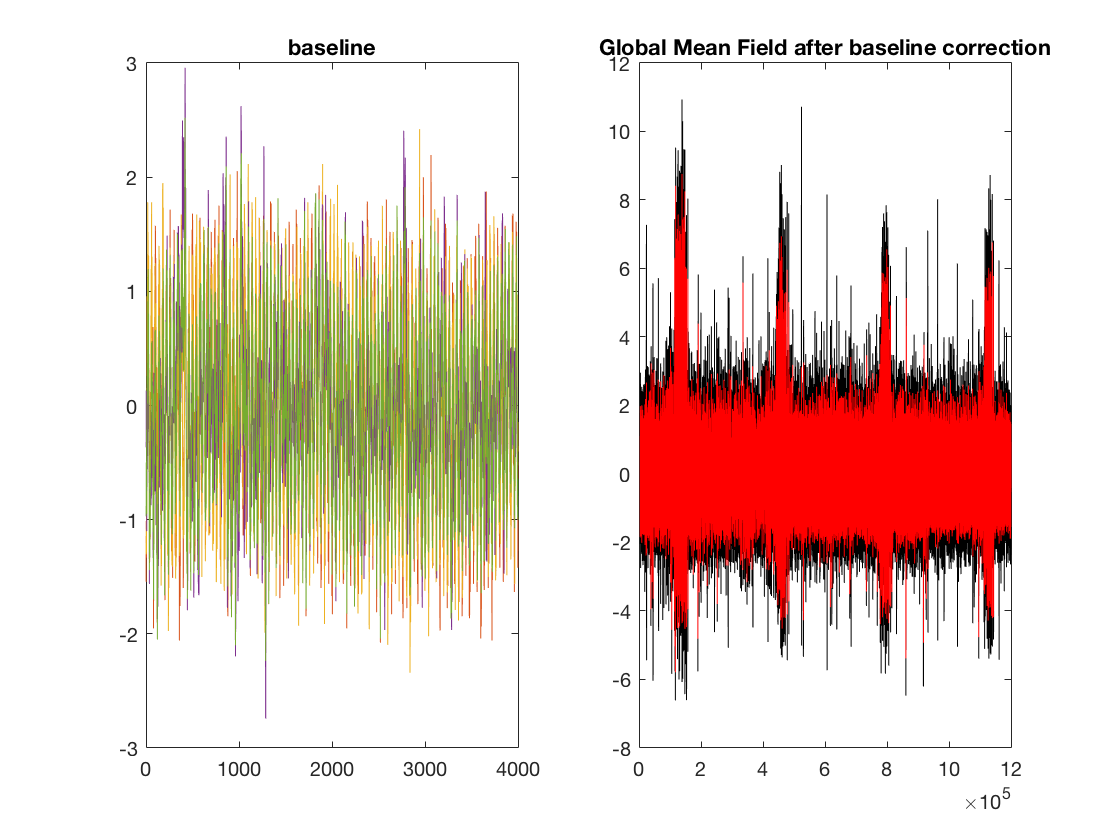

rho_dec = min(find(rho < 0.5));
rho_dec1 = min(find(tau < 0.5));
t_onset = rho_dec; %same as rho_dec1       


%[minr, t_row] = min(abs(rho));
%[minrho, t_col] = min(minr);
%t_onset = min(t_col,t_row(t_col));

% onset based on ictals label
% onset_lb = floor(ictals(1));
% if t_onset > onset_lb
%    t_onset = onset_lb; 
% end
onset = (t_onset-1)*fs;

EEG_seizure = EEG_t(onset+1: N,:); 
EEG_ch = EEG_seizure(:,1);
%  baseline_corrected
EEG_seizure0 = EEG_seizure - repmat(mean(EEG_t_avg(1: t_onset,:), 1),size(EEG_seizure,1), 1);
% Z-score Normalization
EEG_seizure = EEG_seizure0./std(EEG_seizure0, 1);
% GMFP
m = mean(EEG_seizure, 2);
GMF = m;
k = length(EEG_seizure);
%GMF = sqrt(mean((MEA_seizure-repmat(m, 1, size(MEA_seizure, 2))).^2,2)); 

figure,
subplot(1, 2, 1)
plot(1:onset,EEG_seizure(1:onset,:));
%note wrong: xlim([0 onset+10])
%xticks(int32(1: k/7: onset))
title('baseline');
subplot(1, 2, 2)
plot(onset+1: N, EEG_seizure,'k');
hold on;
plot(onset+1: N, GMF,'r');
%xlim([onset+1 k+10+onset+1])
%xticks(int32(onset+1: k/5: N))
%xticklabels(num2str(onset+1: k/5: N))
title('Global Mean Field after baseline correction');


EEGy_ch = EEG_seizure(:,ch);

datalabel = load('EEG_slice01_01_LABELS.mat');
ictals = table2array(datalabel.labels);

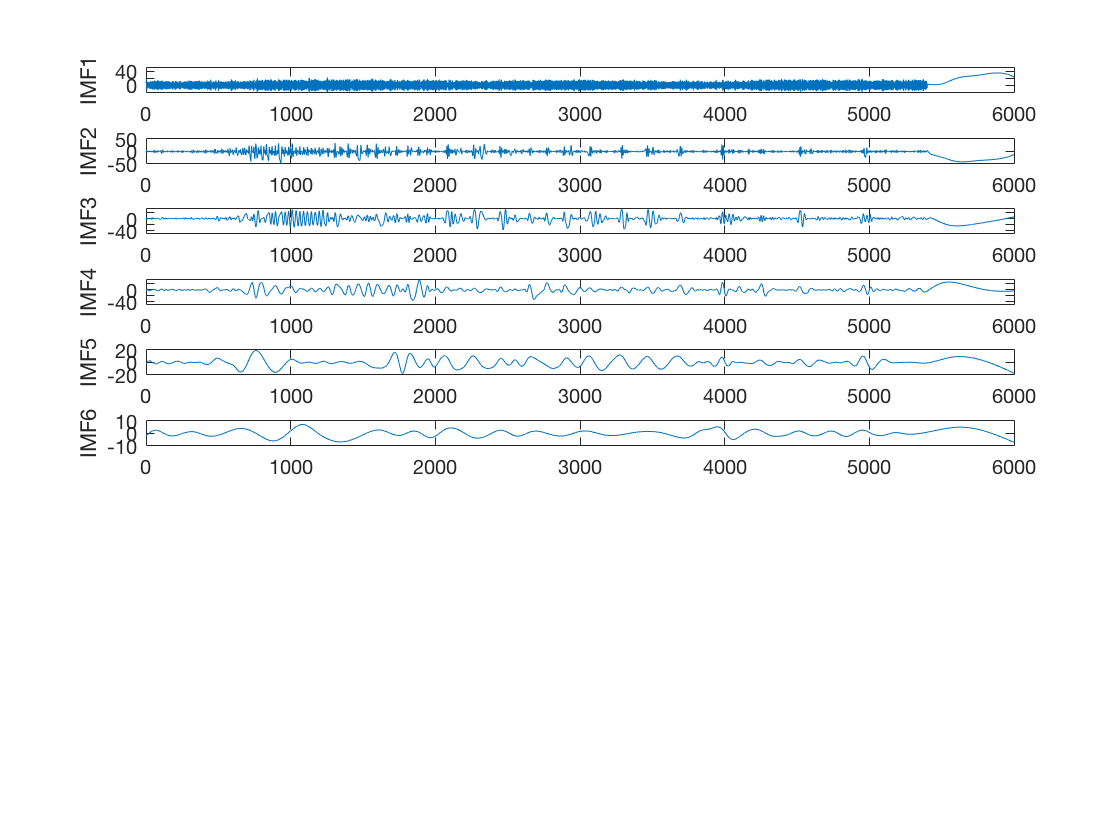

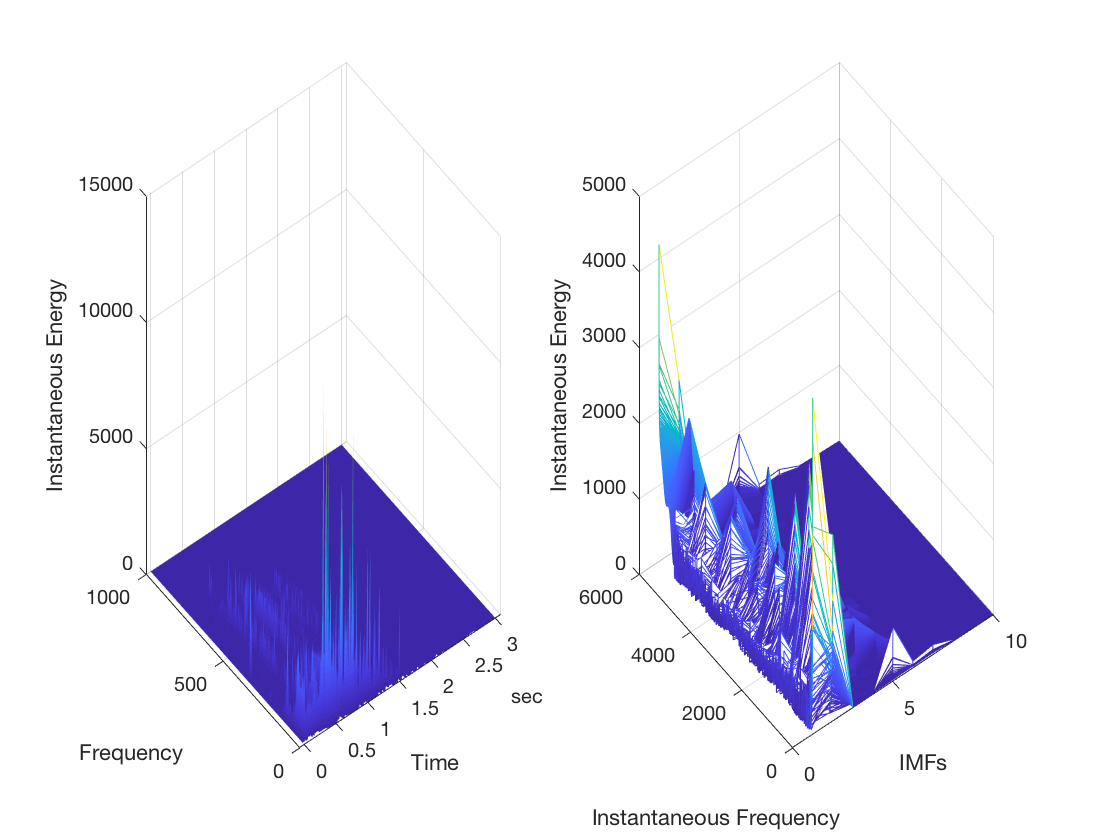

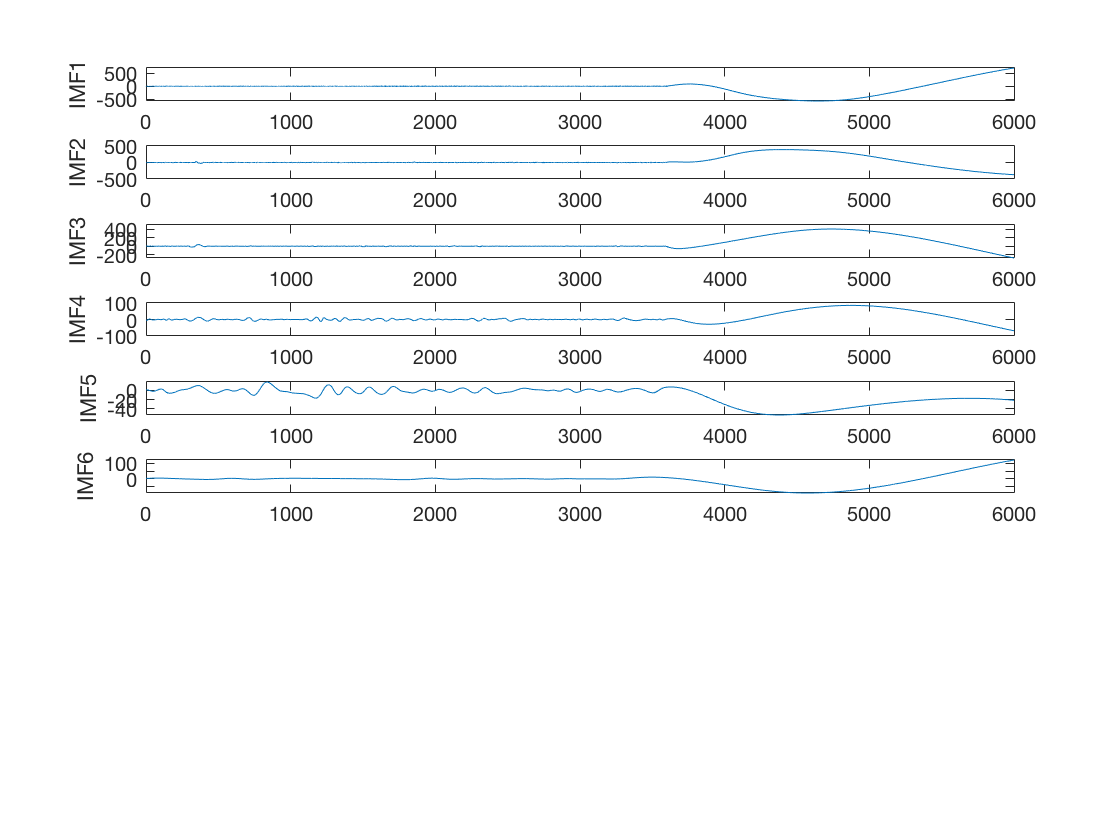

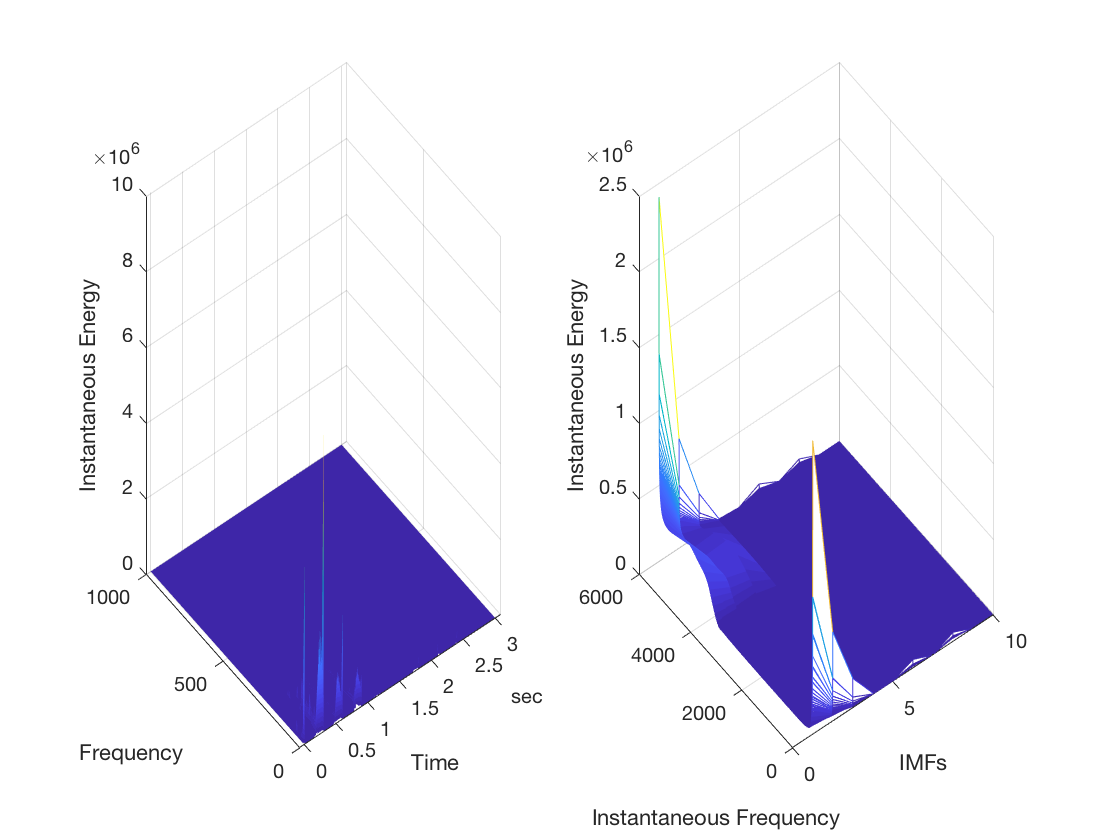

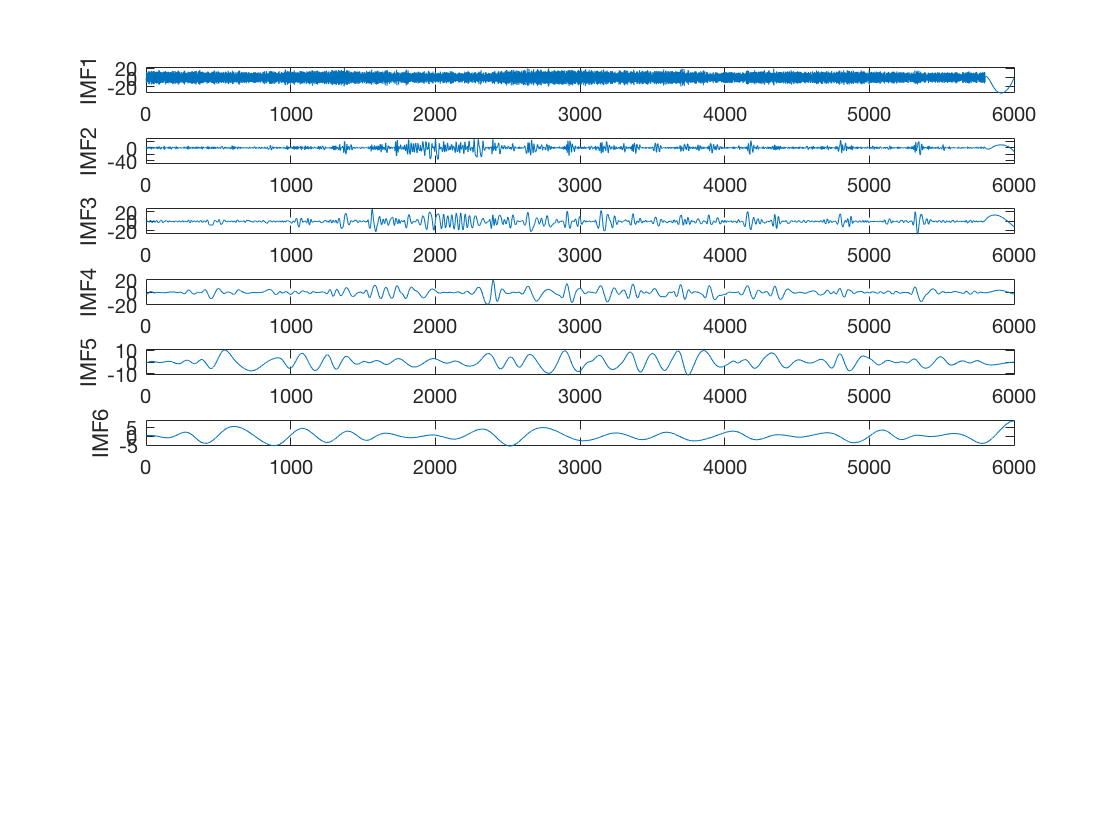

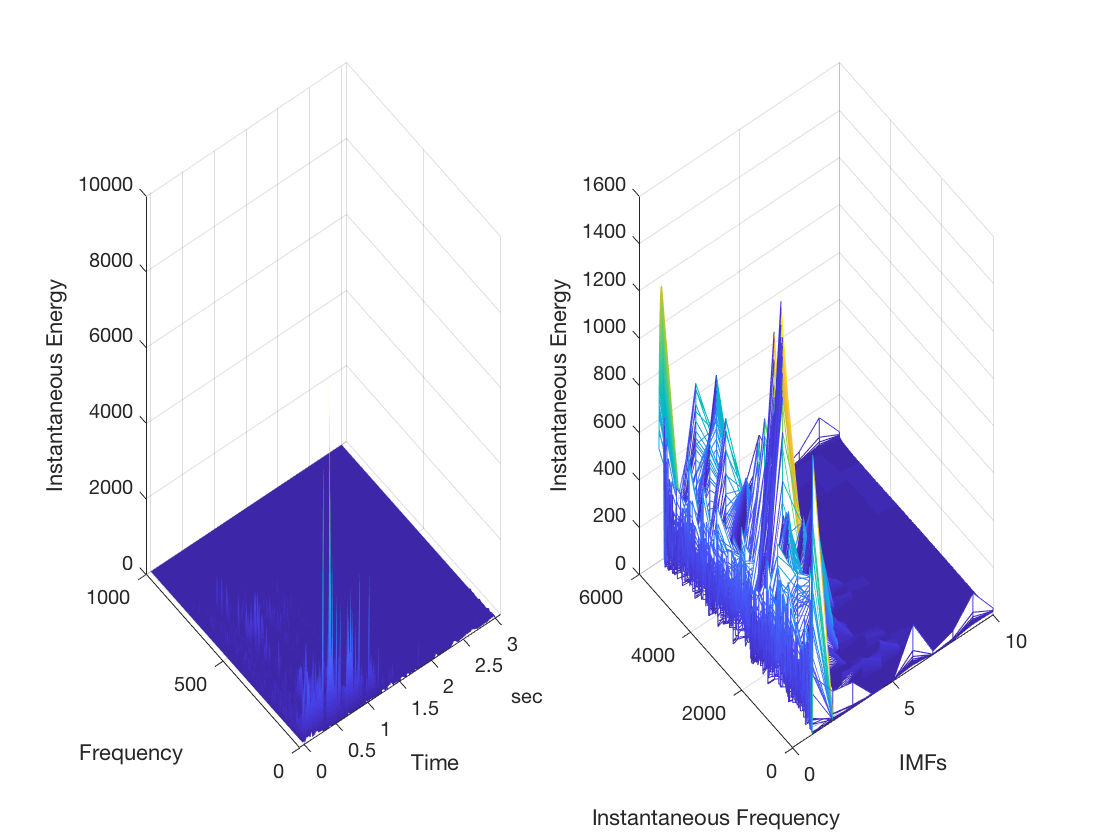

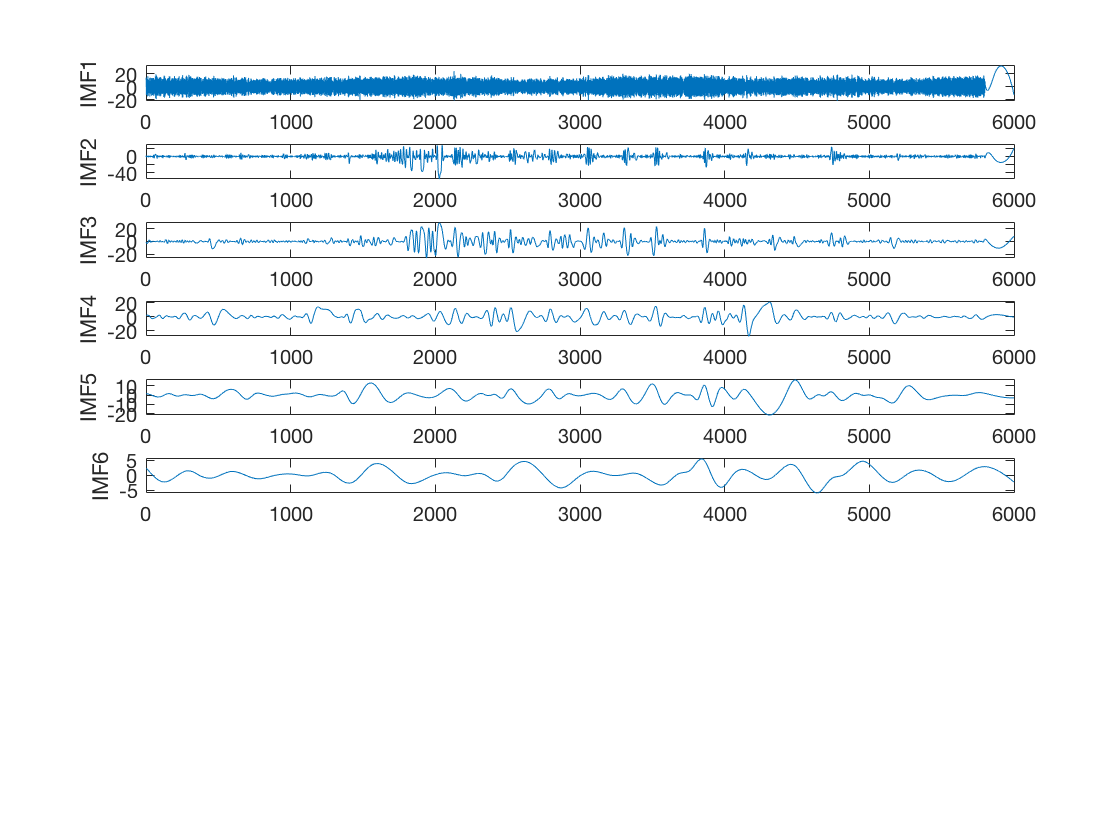

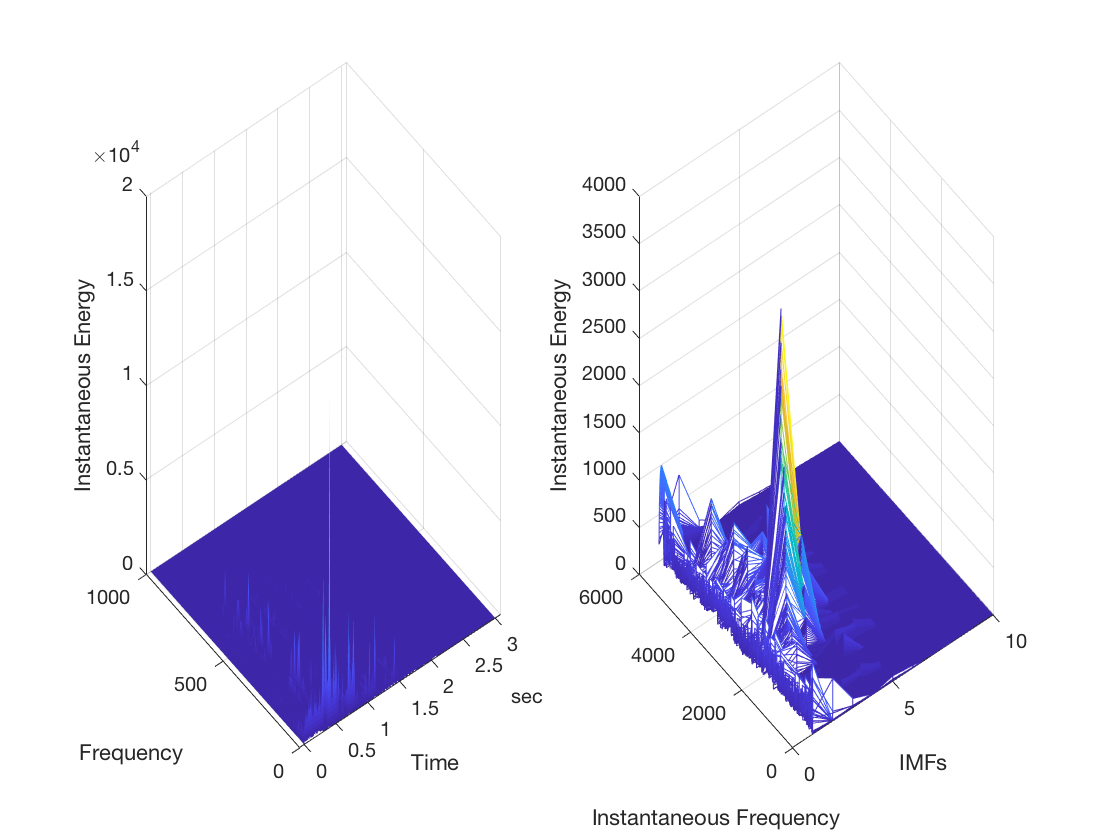


%IMF
type = ["interictal","ictal", "ictal", "interictal",  "interictal"];
group = [0,1,1,0,0];
y = [-1,1,1,-1,-1];
%[Asym, Dur, ypred, lml_cor3] = ictalclassify(ictal_n_interv, fs, asym, dur, type, group, y, ch)

% ictal, inter-ictal 
ictal_n_interv = zeros(60000,5);
for i = 1:size(ictals, 1)
    ictal_n_interv(1:length((floor(ictals(i,1))-1)*bin+1: (floor(ictals(i,2))+1)*bin),i) = EEG_t((floor(ictals(i,1))-1)*bin+1: (floor(ictals(i,2))+1)*bin);
end
EEG = ictal_n_interv(1:10:size(ictal_n_interv, 1), :);

[yupper,ylower] = envelope(EEG);
[M, N] = size(EEG); 
SE = zeros(M, N);
IMFN = 10;
imf = zeros(M, IMFN, N);
for i = 1:N
    %empirical mode decompose 
    figure(2*i-1),
    title('IMF')
   [imftemp,residualtemp,info] = emd(EEG(:,i),'MaxNumIMF',10, 'Display',0);%hide table
   imf(1:size(imftemp,1), 1:size(imftemp,2), i) = imftemp;
   residualtemp(1:size(residualtemp,1), 1:size(residualtemp,2), i) = residualtemp;   
%   figure, have to plot by mysef somehow
%   plot(imf)
    subplot(size(imftemp,2), 1, 1)
    plot(imf(:,1,i))
    ylabel('IMF1')
    subplot(size(imftemp,2), 1, 2)
    plot(imf(:,2,i)) 
    ylabel('IMF2')
    subplot(size(imftemp,2), 1, 3)
    plot(imf(:,3,i))
    ylabel('IMF3')
    subplot(size(imftemp,2), 1, 4)
    plot(imf(:,4,i))
    ylabel('IMF4')
    subplot(size(imftemp,2), 1, 5)
    plot(imf(:,5,i))
    ylabel('IMF5')
    subplot(size(imftemp,2), 1, 6)
    plot(imf(:,6,i))
    ylabel('IMF6')
    
   figure(2*i),
   [hs,f,t,imfinsf(1:size(imf,1),1:size(imf,2),i),imfinse(1:size(imf,1),1:size(imf,2),i)] = hht(imf(:, :, i), fs);
   subplot(1, 2, 1)
   mesh(seconds(t),f,hs,'EdgeColor','none','FaceColor','interp')
   xlabel('Time')
   ylabel('Frequency')
   zlabel('Instantaneous Energy')
   
   subplot(1, 2, 2)
   mesh(imfinse(1:size(imf,1),1:size(imf,2),i),imfinse(1:size(imf,1),1:size(imf,2),i));
   xlabel('IMFs')   
   ylabel('Instantaneous Frequency')
   zlabel('Instantaneous Energy')
   
   mdl = fit([1: size(yupper,1)]', 0.5*(yupper(:,i)+ylower(:,i)), 'poly3', 'Normalize','on', 'Robust','Bisquare'); 
   h(:,i) = EEG(:, i)- mdl(1:M);
   k = 1;
   hk(:,k) = abs(h(:,i) - mean(h(:,i) , 1));
%   [~,~,~,Hk,~]= hht(hk(:,k), fs) 
   SD = abs(hk(:,k) - abs(hk(:,k)  - mean(hk(:,k) , 1))).^2./abs(hk(:,k) - mean(hk(:,k) , 1)).^2;   
   while  sum(SD > mean(SD))>0.001*i*M & k < size(imf,2) -1
       hk(:,k+1)  = abs(hk(:,k) - mean(hk(:,k) , 1));
       dif= imf(:,k)-hk(:,k+1);
       SD = SD + abs(hk(:,k) - abs(hk(:,k+1)  - mean(hk(:,k+1), 1))).^2./abs(hk(:,k+1) - mean(hk(:,k+1) , 1)).^2;          
       k = k+1;
   end
   if k >1       
       SE(:,i) = sum(hk./repmat(sum(hk,2),[1, size(hk,2)]).*log(hk./repmat(sum(hk,2),[1,size(hk,2)])),2);
%       SEH(:,i) = sum(Hk./repmat(sum(Hk,2),[1, size(Hk,2)]).*log(Hk./repmat(sum(Hk,2),[1,size(Hk,2)])),2);
   else
       SE(:,i) = hk/sum(hk).*log(hk/sum(hk))+(1-hk/sum(hk)).*log(1-hk/sum(hk));
%       SEH(:,i) = Hk/sum(Hk).*log(Hk/sum(Hk))+(1-Hk/sum(Hk)).*log(1-Hk/sum(Hk));
   end
   clear hk Hk SD mdl hs
end

difE = SE-mean(imfinse,2);

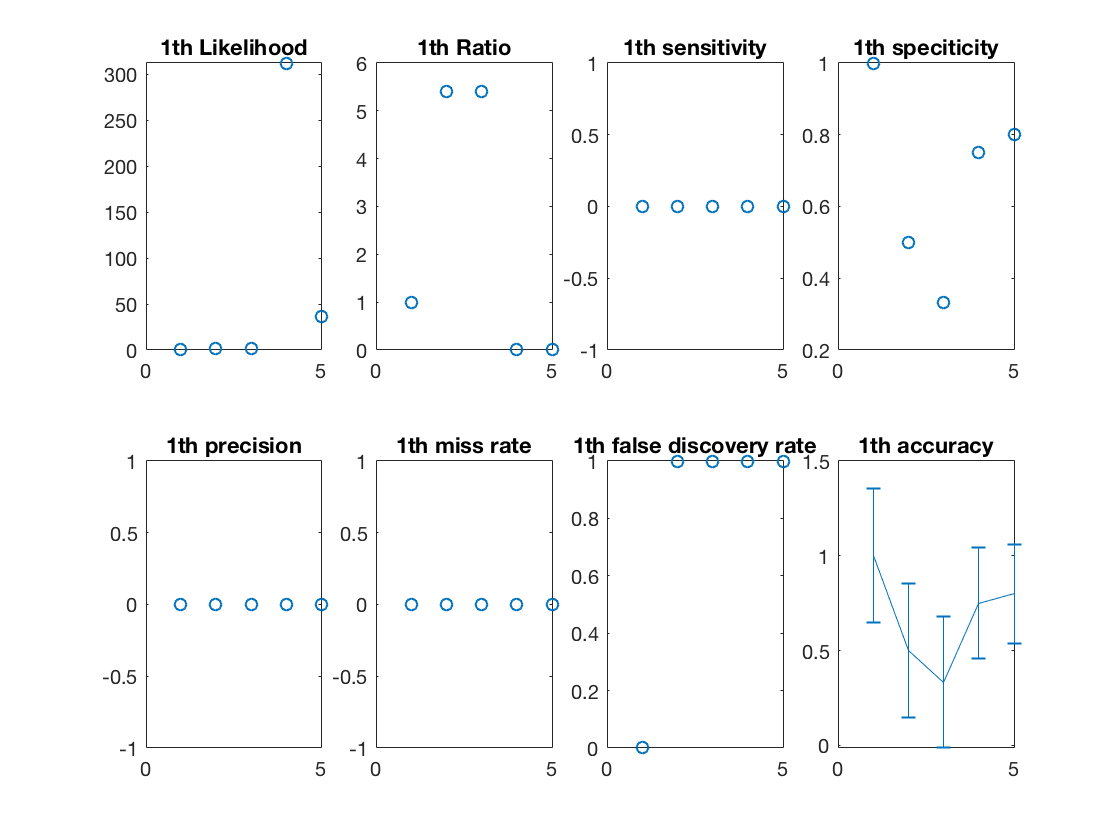

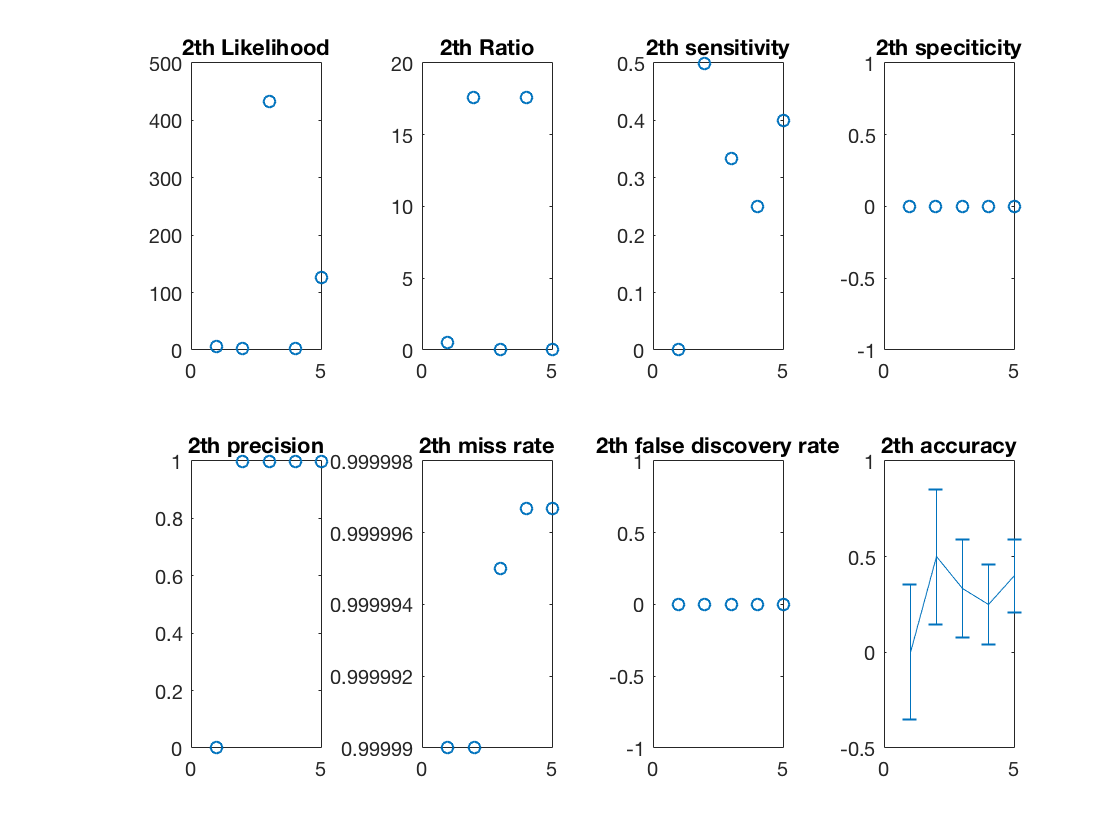

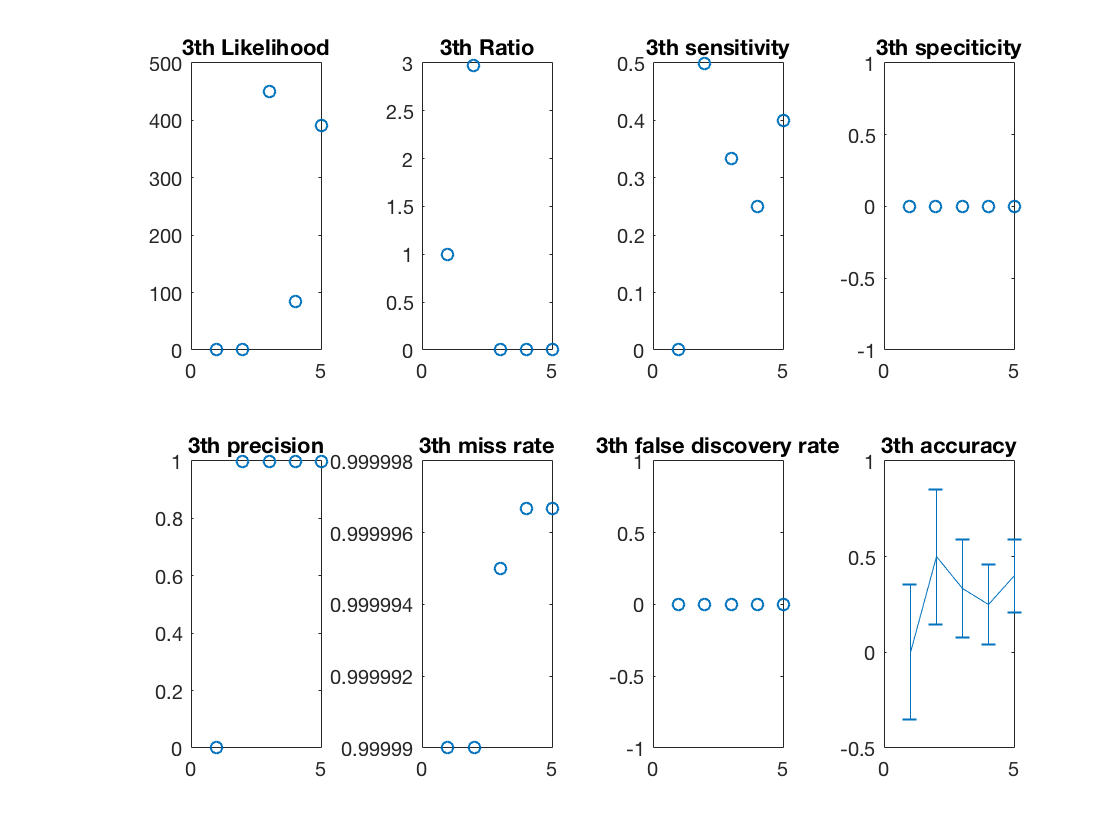

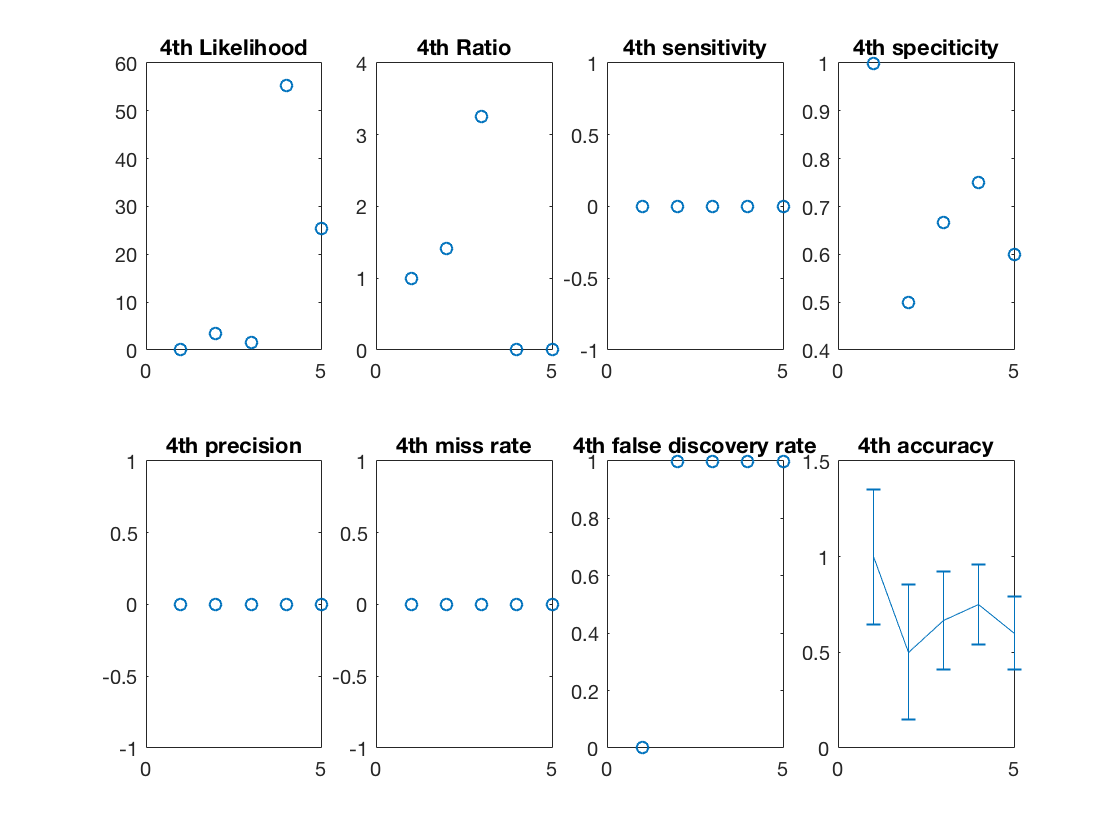

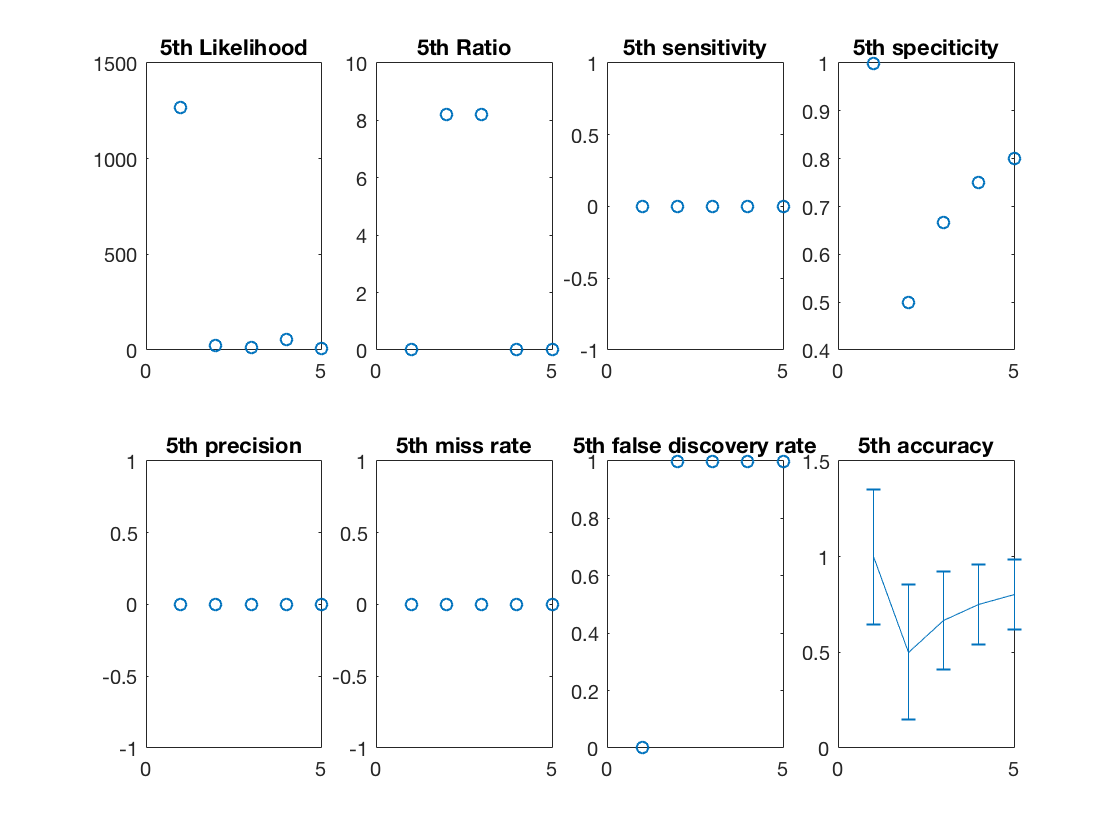

%HIS(fixed tempering) of ictal type 
%logistic regression with regulation
K = [1, 2, 5, 10, 100];
%threshold1 = 80;
%threshold2 = 120;
%fn = 0:bin-1;
%f = 1.0*double(fn)/double(bin-1);
%t = -0.5:1/bin:0.5;  % Time vector 
%L = length(t)-1;      % Signal length
%X = 1/(4*sqrt(2*pi*0.01))*(exp(-t(1:L).^2/(2*0.01)));
%fX = fft(MEA_ch(1: bin: Pnts)).*X;
%ni = find(MEA_ch > threshold);  
ypred = zeros(1, N);        
L = zeros(length(K), N);
LC = [zeros(5,1), ones(5,1), ones(5,1), zeros(5,1), zeros(5,1)];
Ratio = zeros(length(K), N);
TPR= zeros(length(K), N);
TNR = zeros(length(K), N);
PPV = zeros(length(K), N);
FNR = zeros(length(K), N);
FDR = zeros(length(K), N);
ACC = zeros(length(K), N);
STDACC = zeros(length(K), N);
% Mu = ze(length(ctx), 1);
% Eta = zeros(idN, idN);
% Kse = zeros(idN, idN);
    for k = 1:N
%    k = 1;
%    for k =
%    1:length(ctx)
%    for k = 1:7
%    for k = 59:length(ctx) 
%for k = 54:length(ctx);
            SEtemp = SE(:,k); 
            Ektemp = mean(imfinse(:,:,k),2);
            Rho = zeros(M ,length(K));
            for i = 1: length(K);
                li = K(i);  
                [Counts, Centers] = hist(SEtemp, li);        
%                Ptemp = normpdf(SEtemp, mean(Centers), std(Centers));
                if i == length(K)
                    li_N = M - (li-1)*round(M/li); % batchsize
                    ptemp = normpdf(SEtemp((li-1)*round(M/li)+1:M));
                    qtemp = sqrt(2*Ektemp((li-1)*round(M/li)+1:M));
                else
                    li_N = round(M/li);
                    ptemp = normpdf(SEtemp((li-1)*li_N+1:li*li_N));
                    qtemp = sqrt(2*Ektemp((li-1)*li_N+1:li*li_N));
                end
                ptemp(isnan(ptemp)) = 0;
                ptemp(isinf(ptemp)) = 1;
%                Etatemp = repmat(0.1, 1, li_N);
    %            Ztemp = normpdf(Centers, mean(Centers), std(Centers));  
                Ztemp = Centers(i)-li_N/2;
                gamma = normpdf(qtemp, mean(qtemp), std(qtemp));                
%                beta0 = 1/li_N;
                alpha = rand(1);
                rho0 = gamma(1)/alpha;
                c = 1;
                while li >0
                    steps = 5;
                    if (li-1)*li_N+1 > M
                        if i == length(K)
                            li_N = M - (li-1)*round(M/li); % batchsize
                            ptemp = normpdf(SEtemp((li-1)*round(M/li)+1:M));
                            qtemp = sqrt(2*Ektemp((li-1)*round(M/li)+1:M));
                        else
                            li_N = round(M/li);
                            ptemp = normpdf(SEtemp((li-1)*li_N+1:li*li_N));
                            qtemp = sqrt(2*Ektemp((li-1)*li_N+1:li*li_N));
                        end
                    elseif li == 0
                        break
                    end
                    while steps >0   
                        Etatemp = repmat(0.1, 1, li_N);
                        lpd = gradient(ptemp);
                        Utemp = -log(lpd);
                        Utemp(isinf(Utemp)) = 0;
                        for j = 1: (min(li_N,length(Utemp)))
                            if j == 1
                                temp = -log(lpd);
                                temp(isinf(temp)) = 0; 
                                Utemp(j) = max(temp(j), Ztemp);
                                rho = rho0;
                                qtemp = sqrt(Utemp);
                            end
                           %tempering
                           rho = rho - Etatemp(j)/2.*Utemp(j);
                           Ztemp = Ztemp + Etatemp(j).*rho;  
                           qtemp = qtemp / alpha^li_N;
                           qtemp(isnan(qtemp)) = 0;
                           qtemp(isinf(qtemp)) = 1;
                           ptemp = ptemp .* sqrt(2*qtemp)./(qtemp(1)+0.000001);
                           ptemp(isnan(ptemp)) = 0;
                           ptemp(isinf(ptemp)) = 1;
                           lpd = gradient(ptemp);
                           Utemp = -log(lpd);
                           Utemp(isinf(Utemp)) = 0;
                           Utemp(isnan(Utemp)) = 0;                           
                           alphatemp = rand(1);
                           if j == min(li_N,length(Utemp))
                               alphatemp = 1/alpha;
                           end

                           rho = alphatemp*(rho - Etatemp(j)/2.*Utemp(j));
                           alpha = alpha*alphatemp;
                           Rho(min(j,length(Utemp))+c -1, i) = rho; 
                        end
                        if sum(ptemp ~= 0)*sum(qtemp ~= 0) == 0 
                            if i == length(K)
                                li_N = M - (li-1)*round(M/li); % batchsize
                                ptemp = normpdf(SEtemp((li-1)*round(M/li)+1:M));
                                qtemp = sqrt(2*Ektemp((li-1)*round(M/li)+1:M));
                            else
                                li_N = round(M/li);
                                if (li-1)*li_N+1 >M
                                    break
                                elseif li*li_N > M
                                    ptemp = normpdf(SEtemp((li-1)*li_N+1:M));
                                    qtemp = sqrt(2*Ektemp((li-1)*li_N+1:M));
                                else
                                    ptemp = normpdf(SEtemp((li-1)*li_N+1:li*li_N));
                                    qtemp = sqrt(2*Ektemp((li-1)*li_N+1:li*li_N));
                                end
                            end
                        end
                        ptemp = ptemp(ptemp ~= 0);
                        ptemp = ptemp/max(ptemp);
                        qtemp = qtemp(qtemp ~= 0);
                        p = ptemp(length(ptemp))* sqrt(2*qtemp(1));
                        q = qtemp(1)/ rand(1)^li_N;
                        q(isinf(q)) = 1;
                        l = abs(log(max(p,1e-16)) - log(max(q,1e-16)));
                        Ztemp = min(real(Ztemp), 10*l);
                        l = max(l, real(Ztemp));
                        steps = steps -1;
                        %configure
                        if L(i, k) < l | Ratio (i) < abs(p/q)
                            L(i, k) = l;
                            Ratio(i, k) = abs(p/q); 
                        elseif abs(p/(p+q)) == Ratio(i, k) |steps == 0
                            break;
                        end
                        if j == min(li_N,length(Utemp))
                            c = c + li_N;
                            li = li - 1; 
                            if li == 0
                                break
                            end
                        end
                    end                
                end
%                clear rho Ztemp qtemp ptemp lpd Utemp p q l
                %according to definition:  r = d/(1-d),(y = 1|x)/(y =
                %0|x)
                %sensitivity, speciticity, precision, miss rate, false discovery rate
%                L(:, k) = (L(:, k) - mean(L(:, k)));
                TPR(i,k) = sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==1)/(sum(LC(1:i,k)==1)+0.00001);
                TNR(i,k) = sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==0)/(sum(LC(1:i,k)==0)+0.00001);
                PPV(i,k) = sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==1)/(sum(abs(L(1:i,k))> mean(abs(L(1:i,k))))+0.00001);
                FNR(i,k) = sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==1)/(sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==1)+ sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==0)+0.00001);
                FDR(i,k) = sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==0)/(sum(abs(L(1:i,k))>mean(abs(L(1:i,k))))+0.00001);            
                ACC(i,k) = (sum(abs(L(1:i,k))>mean(abs(L(1:i,k))) & LC(1:i,k)==1)+sum(abs(L(1:i,k))<=mean(abs(L(1:i,k))) & LC(1:i,k)==0))/i;
                STDACC(i,k) = std(ACC(1:i,k));
                STDACC(isnan(STDACC)) = 0;
            end
    end
    for k = 1: N
            figure,
            subplot(2, 4, 1)
            plot(L(:,k),'o')
            title([num2str(k),'th Likelihood'])
            subplot(2, 4, 2)
            plot(Ratio(:,k),'o')
            title([num2str(k),'th Ratio'])
            subplot(2, 4, 3)        
            plot(TPR(:,k),'o')
            title([num2str(k),'th sensitivity'])
            subplot(2, 4, 4)        
            plot(TNR(:,k),'o')
            title([num2str(k),'th speciticity'])
            subplot(2, 4, 5)        
            plot(PPV(:,k),'o')
            title([num2str(k),'th precision'])
            subplot(2, 4, 6)        
            plot(FNR(:,k),'o')
            title([num2str(k),'th miss rate'])
            subplot(2, 4, 7)        
            plot(FDR(:,k),'o')
            title([num2str(k),'th false discovery rate'])
            subplot(2, 4, 8)
            STDACC(1,k) = STDACC(2,k);
            errorbar(1:size(ACC(:,1)),ACC(:,k), STDACC(:,k));
            title([num2str(k),'th accuracy'])                
    end

 ypred(mean(abs(L), 2)>mean(mean(abs(L),2))) = 1;
 ypred(mean(abs(L), 2)<=mean(mean(abs(L),2))) = -1;
 accuracy = (sum(ypred == y))./length(y)

accuracy = 0.6000